# Cart-Pole Stochastic Control

## State Space Representation

See "wheeled_balancer_model_eqtns.mlx" and "wheeled_balancer_model.mlx" for derivation of equations of motion and real values of system parameters.

% outputting both the x-position and theta-angle
A = [0    1.0000         0         0
         0   -7.0198   -4.2395         0
         0         0         0    1.0000
         0   86.6165  173.2330         0];
B =[0
    4.2385
         0
  -52.2983];
C = [1 0 0 0; 0 0 0 1];
D = [0;0];
states = {'x' 'x_dot' 'theta' 'theta_dot'};
inputs = {'u'};
outputs = {'x'; 'theta'};
cplant = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)


cplant =
 
  A = 
                      x      x_dot      theta  theta_dot
   x                  0          1          0          0
   x_dot              0      -7.02     -4.239          0
   theta              0          0          0          1
   theta_dot          0      86.62      173.2          0
 
  B = 
                  u
   x              0
   x_dot      4.239
   theta          0
   theta_dot  -52.3
 
  C = 
                  x      x_dot      theta  theta_dot
   x              1          0          0          0
   theta          0          0          0          1
 
  D = 
          u
   x      0
   theta  0
 
Continuous-time state-space model.


## Discretization

T = 1/100; % 0.01s, 100Hz
plant = c2d(cplant,T);
[G, H, Cd, Dd] = ssdata(plant)

G =     1.0000    0.0097   -0.0002   -0.0000
         0    0.9322   -0.0411   -0.0002
         0    0.0042    1.0086    0.0100
         0    0.8389    1.7193    1.0086


H =     0.0002
    0.0410
   -0.0026
   -0.5065


Cd =      1     0     0     0
     0     0     0     1


Dd =      0
     0


## SS Feedback PI Control Gains; Discrete

### Theory:

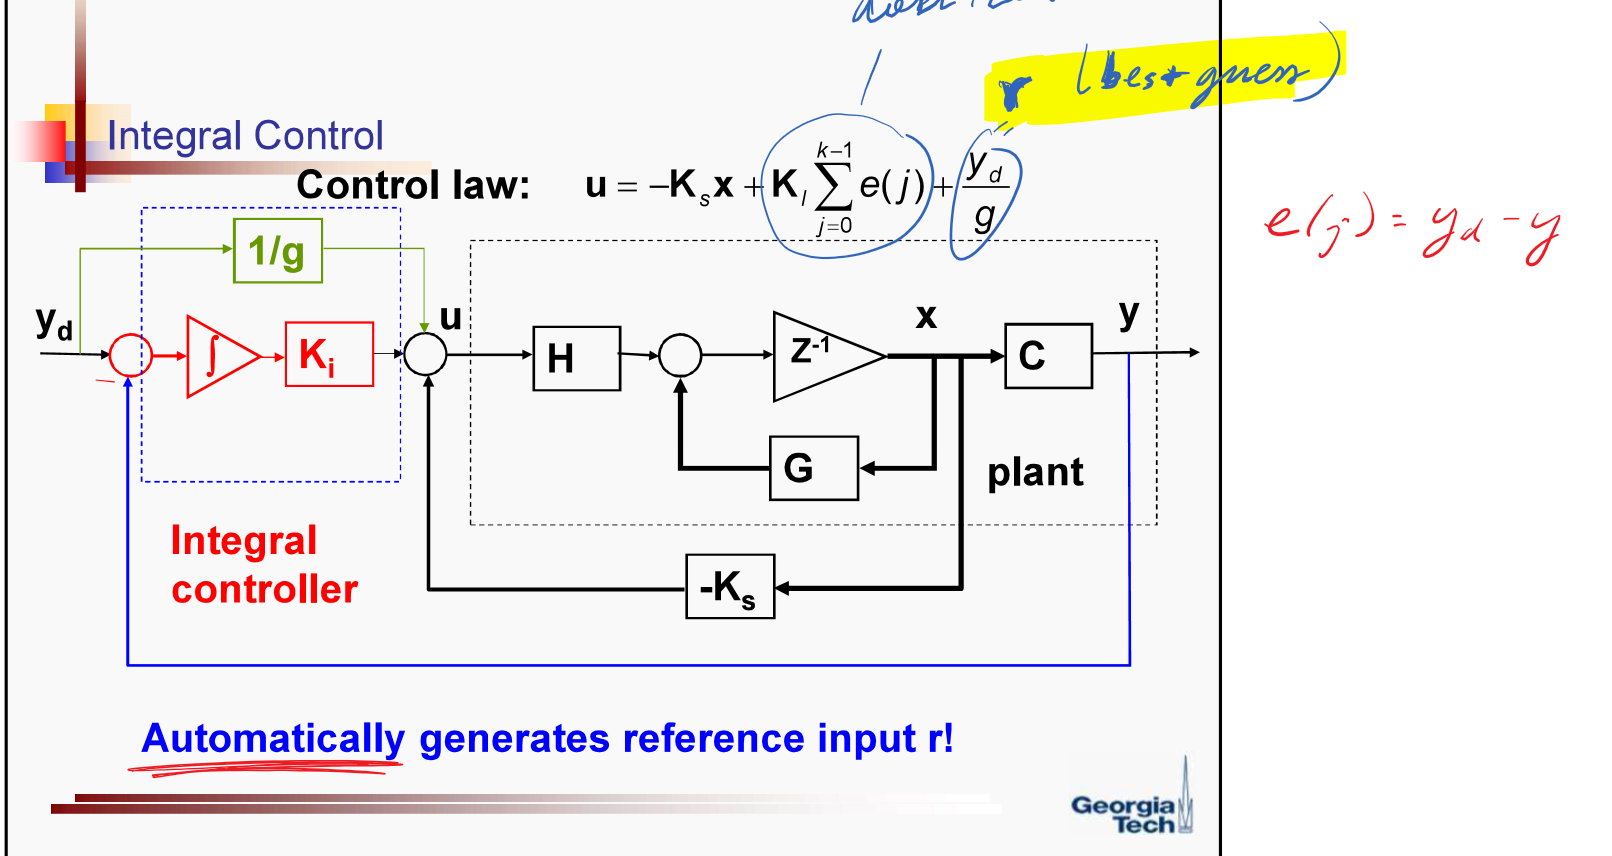

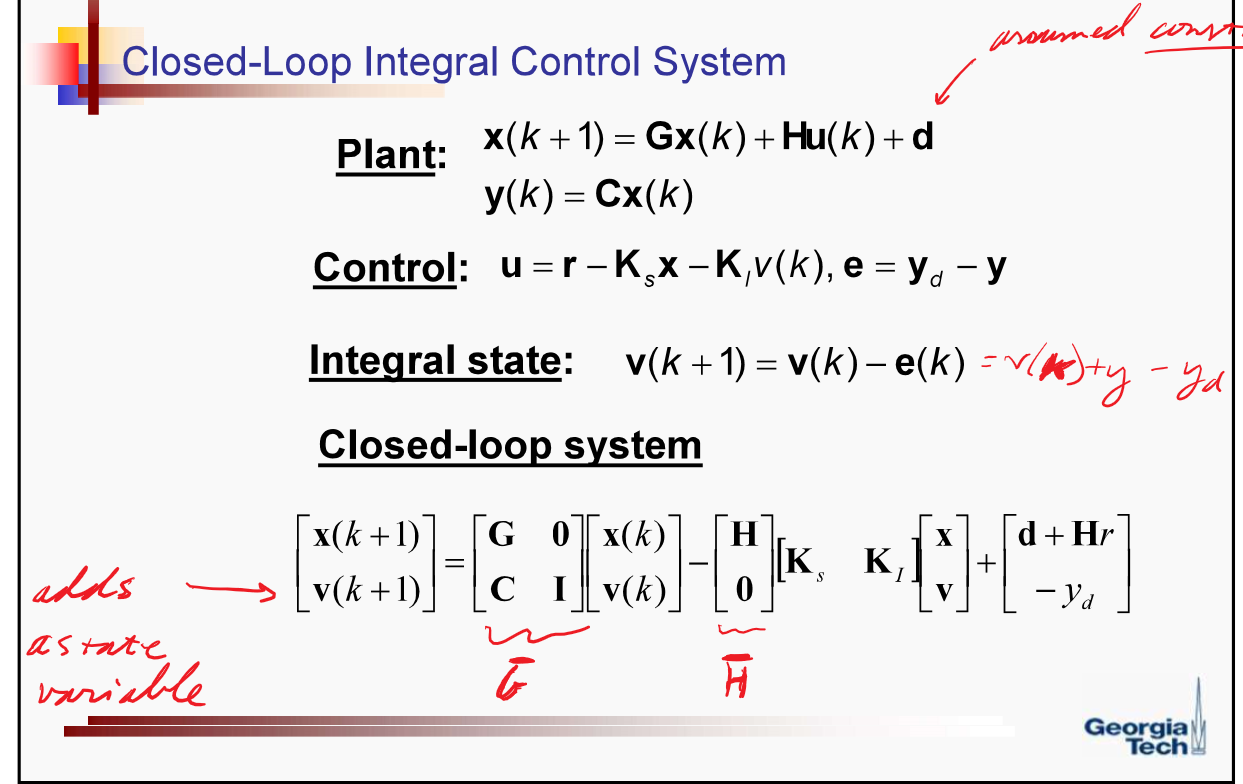

### Implementation:

Gbar = [G zeros(4,1); Cd(1,:) 1]

Gbar =     1.0000    0.0097   -0.0002   -0.0000         0
         0    0.9322   -0.0411   -0.0002         0
         0    0.0042    1.0086    0.0100         0
         0    0.8389    1.7193    1.0086         0
    1.0000         0         0         0    1.0000


Hbar = [H; 0]

Hbar =     0.0002
    0.0410
   -0.0026
   -0.5065
         0


% desired close-loop pole locations:
pc = [-3, -4, -6, -9, -10];
pd = exp(T*pc)

pd =     0.9704    0.9608    0.9418    0.9139    0.9048


K = acker(Gbar, Hbar, pd)

K =   -10.8317   -5.7073  -11.0581   -0.9188   -0.1115


Gcl = Gbar - Hbar*K

Gcl =     1.0022    0.0108    0.0021    0.0002    0.0000
    0.4437    1.1660    0.4120    0.0374    0.0046
   -0.0277   -0.0104    0.9803    0.0077   -0.0003
   -5.4865   -2.0520   -3.8819    0.5432   -0.0565
    1.0000         0         0         0    1.0000


yd = 0.5; r = 0; 
% r is 0 because the error (yd - y) automatically generates the reference input


## Step Response; deterministic observations

To simulate the step response, we need two things: 

- a function to propagate the state space given the plant model and control efforts

- function to generate the control effort, given observations (i.e. states of system)

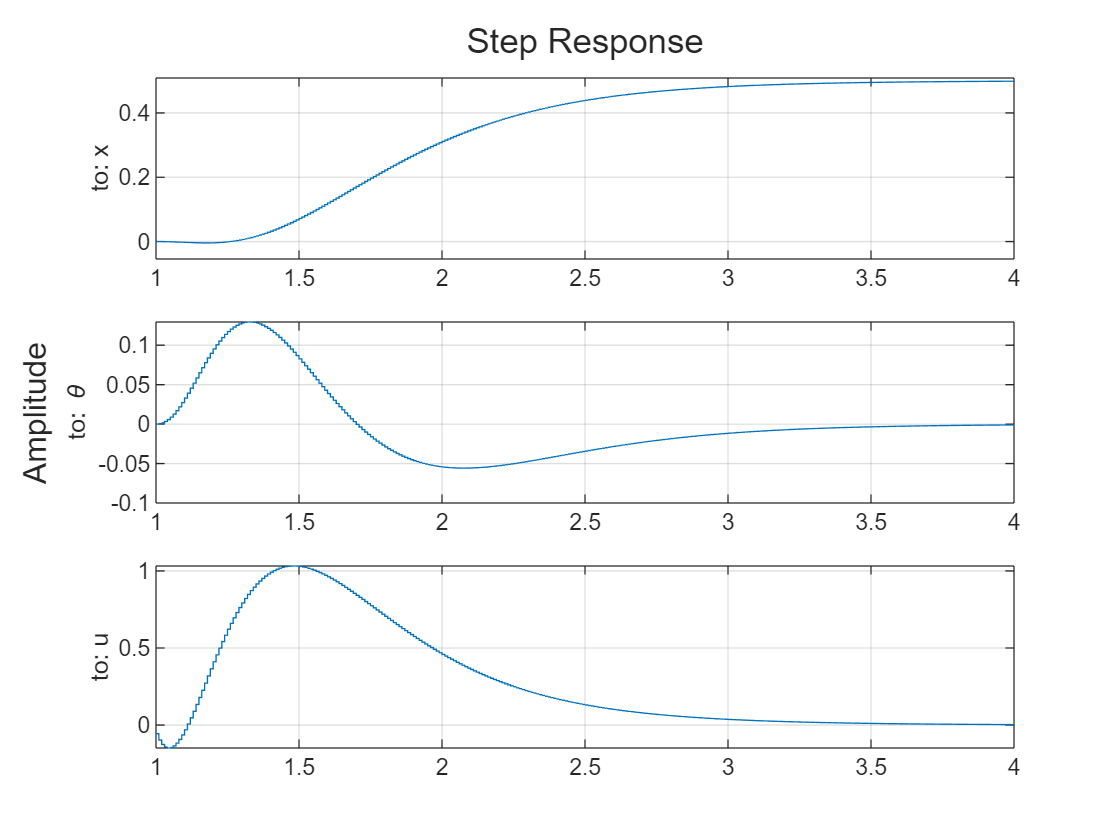

% system equations
vk2 = @(vk,y_meas,y_des) vk + y_meas - y_des; % v(k), integral error
uk2 = @(r,xk,vk,Ks,Ki) r - Ks*xk - Ki*vk; % u(k), control effort
xk2 = @(xk,uk,G,H) G*xk + H*uk; % x(k+1), state propagation

% initialize variable arrays
ts = 1:T:4;
y_meas = zeros(size(ts));
vk = zeros(size(ts));
uk = zeros(size(ts));
xk = zeros(4,size(ts,1));

% set initial value of variables
x0 = zeros(4,1); y0 = 0;
v0 = 0;
yd = 0.5;
r = 0;

Ks = K(1:end-1); Ki = K(end);
y_meas(1) = x0(1,1); % xpos of cart
vk(1) = vk2(v0,y0,yd);
uk(1) = uk2(r,x0,vk(1),Ks,Ki);
xk(:,1) = xk2(x0,uk(1),G,H);

% step through system
for i = 2:length(ts)
    y_meas(i) = xk(1,i-1); % xpos of cart
    vk(i) = vk2(vk(i-1),y_meas(i),yd);
    uk(i) = uk2(r,xk(:,i-1),vk(i),Ks,Ki);
    xk(:,i) = xk2(xk(:,i-1),uk(i),G,H);
end

t = tiledlayout(3,1);
title(t,'Step Response')
ylabel(t,'Amplitude')
nexttile;
stairs(ts,xk(1,:)), grid on
ylim([min(xk(1,:))-0.05, max(xk(1,:)) + 0.01])
ylabel('to: x')
nexttile;
stairs(ts,xk(3,:)), grid on
ylabel('to: \theta')
nexttile;
stairs(ts,uk), grid on
ylabel('to: u')

## Step Response; stochastic observations, no filtering

To inspect the effect of having stochastic observations, we add randomness to the x position state observation for the position of the cart.

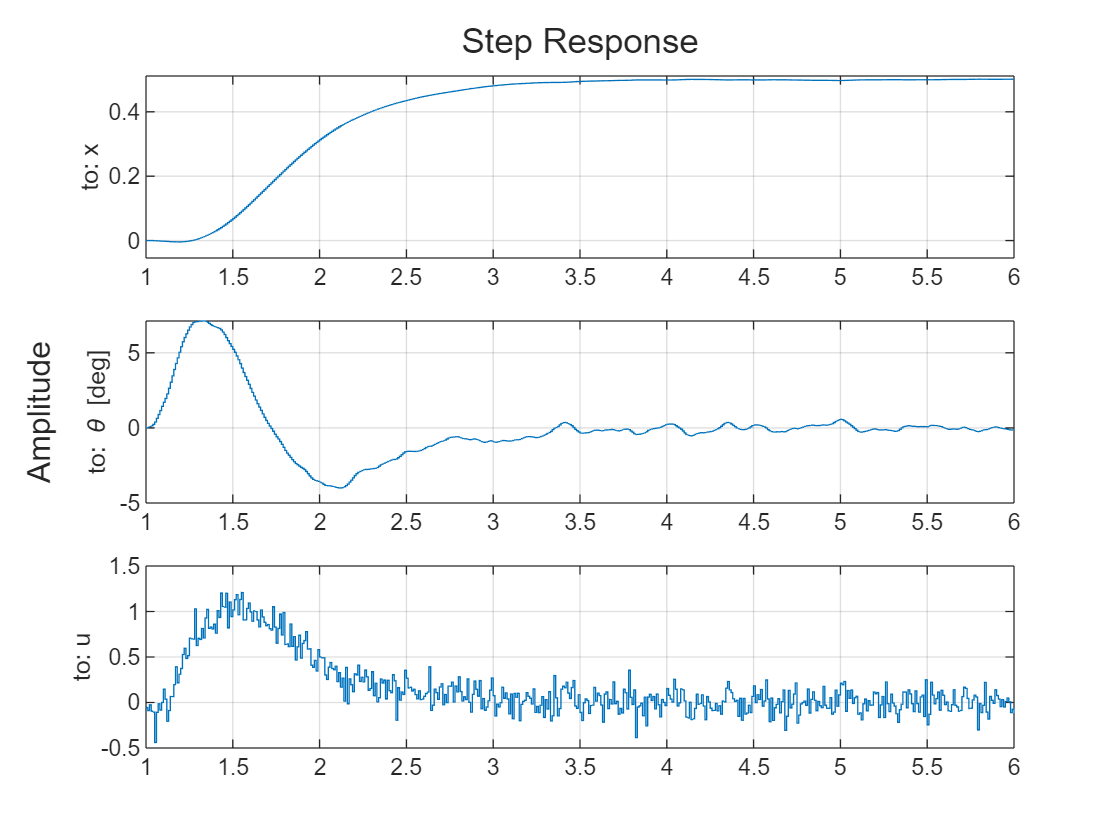

% system equations
vk2 = @(vk,y_meas,y_des) vk + y_meas - y_des; % v(k), integral error
uk2 = @(r,xk_meas,vk,Ks,Ki) r - Ks*xk_meas - Ki*vk; % u(k), control effort
xk2 = @(xk,uk,G,H) G*xk + H*uk; % x(k+1), state propagation

% initialize variable arrays
ts = 1:T:6;
y_meas = zeros(size(ts));
vk = zeros(size(ts));
uk = zeros(size(ts));
xk = zeros(4,size(ts,1));

% set initial value of variables
x0 = zeros(4,1); y0 = 0;
v0 = 0;
yd = 0.5; % [m] target cart position
r = 0;

Ks = K(1:end-1); Ki = K(end);
y_meas(1) = x0(1,1); % xpos of cart
vk(1) = vk2(v0,y0,yd);
uk(1) = uk2(r,x0,vk(1),Ks,Ki);
xk(:,1) = xk2(x0,uk(1),G,H);
sigma = 0.01; % [m] of standard deviation
wk = randn(size(uk))*sigma;

% step through system
for i = 2:length(ts)
    y_meas(i) = xk(1,i-1) + wk(i); % xpos of cart
    vk(i) = vk2(vk(i-1),y_meas(i),yd);
    xk_meas = [y_meas(i); xk(2:end,i-1)];
    uk(i) = uk2(r,xk_meas,vk(i),Ks,Ki);
    xk(:,i) = xk2(xk(:,i-1),uk(i),G,H);
end

t = tiledlayout(3,1);
title(t,'Step Response')
ylabel(t,'Amplitude')
nexttile;
stairs(ts,xk(1,:)), grid on
ylim([min(xk(1,:))-0.05, max(xk(1,:)) + 0.01])
ylabel('to: x')
nexttile;
stairs(ts,xk(3,:)*180/pi), grid on
ylabel('to: \theta [deg]')
nexttile;
stairs(ts,uk), grid on
ylabel('to: u')

## Step Response; stochastic observations, Luenberger observer

To inspect the effect of having stochastic observations, we add randomness to the state observations for the position of the cart.

% system equations
vk2 = @(vk,y_meas,y_des) vk + y_meas - y_des; % v(k), integral error
uk2 = @(r,xk_meas,vk,Ks,Ki) r - Ks*xk_meas - Ki*vk; % u(k), control effort
xk2 = @(xk,uk,G,H) G*xk + H*uk; % x(k+1), state propagation

% initialize variable arrays
ts = 1:T:6;
y_meas = zeros(size(ts));
vk = zeros(size(ts));
uk = zeros(size(ts));
xk = zeros(4,size(ts,1));

% set initial value of variables
x0 = zeros(4,1); y0 = 0;
v0 = 0;
yd = 0.5; % [m] target cart position
r = 0;

Ks = K(1:end-1); Ki = K(end);
y_meas(1) = x0(1,1); % xpos of cart
vk(1) = vk2(v0,y0,yd);
uk(1) = uk2(r,x0,vk(1),Ks,Ki);
xk(:,1) = xk2(x0,uk(1),G,H);
sigma = 0.01; % [m] of standard deviation
wk = randn(size(uk))*sigma;

% step through system
for i = 2:length(ts)
    y_meas(i) = xk(1,i-1) + wk(i); % xpos of cart
    vk(i) = vk2(vk(i-1),y_meas(i),yd);
    xk_meas = [y_meas(i); xk(2:end,i-1)];
    uk(i) = uk2(r,xk_meas,vk(i),Ks,Ki);
    xk(:,i) = xk2(xk(:,i-1),uk(i),G,H);
end

t = tiledlayout(3,1);
title(t,'Step Response')
ylabel(t,'Amplitude')
nexttile;
stairs(ts,xk(1,:)), grid on
ylim([min(xk(1,:))-0.05, max(xk(1,:)) + 0.01])
ylabel('to: x')
nexttile;
stairs(ts,xk(3,:)*180/pi), grid on
ylabel('to: \theta [deg]')
nexttile;
stairs(ts,uk), grid on
ylabel('to: u')